# Robotics 2 - Midterm - April 13, 2016

## Exercise 1

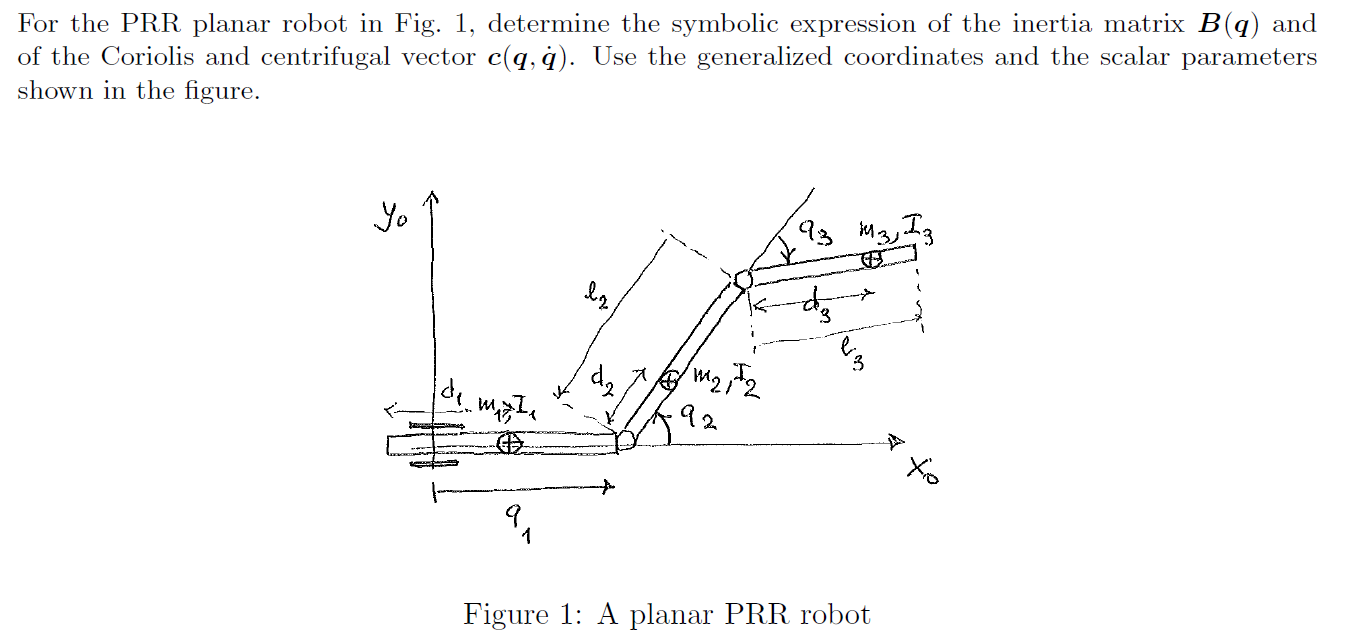

% Initialize variables
syms q1 q2 q3 q1dot q2dot q3dot d2 d3 l2

n=4;
Ui=sym(zeros(n,1));
ck=sym(zeros(n,1));
r0_ci=sym(zeros(3,n));

M=[    a1      0       -a6*sin(q3)-a5*sin(q3+q4)       -a5*sin(q3+q4);...
        0       a2       a6*cos(q3)+a5*cos(q3+q4)        a5*cos(q3+q4);...
-a6*sin(q3)-a5*sin(q3+q4) a6*cos(q3)+a5*cos(q3+q4)  a3+2*a6*l3*cos(q4)  a4+a6*l3*cos(q4);...
-a5*sin(q3+q4) a5*cos(q3+q4)    a4+a6*l3*cos(q4)    a4]

$$M = \begin{array}{l} \left(\begin{array}{cccc} a_{1} & 0 & \sigma_{1} & -a_{5}\,\sin\left(q_{3}+q_{4}\right)\\ 0 & a_{2} & \sigma_{2} & \sigma_{3}\\ \sigma_{1} & \sigma_{2} & a_{3}+2\,a_{6}\,l_{3}\,\cos\left(q_{4}\right) & a_{4}+a_{6}\,l_{3}\,\cos\left(q_{4}\right)\\ -a_{5}\,\sin\left(q_{3}+q_{4}\right) & \sigma_{3} & a_{4}+a_{6}\,l_{3}\,\cos\left(q_{4}\right) & a_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-a_{5}\,\sin\left(q_{3}+q_{4}\right)-a_{6}\,\sin\left(q_{3}\right)\\ \sigma_{2}=\sigma_{3}+a_{6}\,\cos\left(q_{3}\right)\\ \sigma_{3}=a_{5}\,\cos\left(q_{3}+q_{4}\right) \end{array}$$